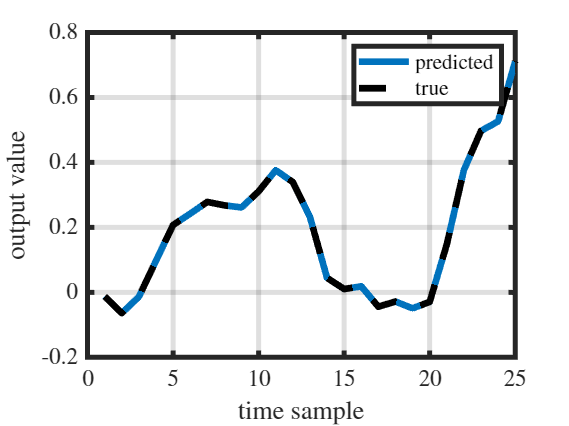

clear; close all;

% Demo dynamics
N = 25;
% State space
A = [0.8, 0.1; 0.2, 0.7];
B = [0.1; 1];
C = [1, 0];
% Lifted form
p = zeros(N,1);
W = B; 
for n = 1:N
    p(n,1) = C*W;
    W = A*W;
end
P = tril(toeplitz(p));

% Training data
J = 3;
u_cell = cell(J,1);
y_cell = cell(J,1);
X_cell = cell(J,1);
for j = 1:J
    u_cell{j,1} = randn(N,1);
    [y_cell{j,1}, X_cell{j,1}] = run_linear_siso_ss_dynamics(A, B, C, zeros(2,1), u_cell{j,1});
end

% Setup GP model
gp_model = CSISOSSGP(2, N, C);

% Train GP model
gp_model.train_gp_model(X_cell, u_cell);

% Prediction
u  = randn(N,1);
y  = P*u;
yp = gp_model.predict(u, zeros(2,1));

% Plot results
figure;
plot(yp); hold on;
plot(y, '--', 'Color', 'black');
xlabel('time sample');
ylabel('output value');
legend('predicted', 'true');


% Test linearization
M = gp_model.linearize_at_input_trajectory(zeros(2,1), u);
disp(norm(P-M));

   7.1943e-04
